**Define Variables**

clear;
R=  6;       % Resistance
L =  5;      % Inductance
Ke = 0.3;     % Back EMF constant
Kt = 0.01;     % Torque constant
J = 0.1;      % Inertia
b =  0.1;      % Friction coefficient
Kp = 10;       % Proportional constant
Kd = 6.2;       % Derivative constant
Ki = 0.02;    % Integral constant

**Define Transfer function**

s= tf('s');
tf = (Kt*(Kp+Kd+Ki)) / ((J*s+b)*(L*s+R)+Kt*(Ke+Kp+(Kd*s)+(Ki/s)-1));

**Simulation**

t = 0:1:50;
refrence_speed = 1;
[y,t] = step(refrence_speed*tf,t);

**plot responce **

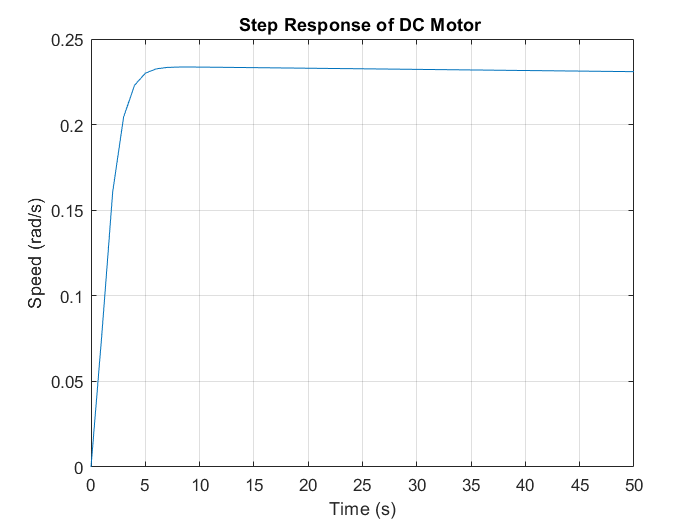

figure    
plot(t,y);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Step Response of DC Motor ');
grid on